y = [676,825,774,716,940,1159,1384,1524,...
    1668,1688,1958,2031,2234,2566,2820,...
    3006,3093,3277,3514,3770,4170];
plot(y,'*-')
hold on
y=y';
n=length(y);
alpha = 0.3;
st1(1)=y(1);
st2(1)=y(1);
for i=2:n
    st1(i)=alpha.*y(i)+(1-alpha).*st1(i-1);
    st2(i)=alpha.*st1(i)+(1-alpha).*st2(i-1);
end
st1

st1 = 	1.0e+03 *

    0.6760    0.7207    0.7367    0.7305    0.7933    0.9030    1.0473    1.1903    1.3336    1.4399    1.5954    1.7261    1.8784    2.0847    2.3053    2.5155    2.6888    2.8652    3.0599    3.2729    3.5420


st2

st2 = 	1.0e+03 *

    0.6760    0.6894    0.7036    0.7117    0.7362    0.7862    0.8646    0.9623    1.0737    1.1836    1.3071    1.4328    1.5665    1.7219    1.8970    2.0825    2.2644    2.4446    2.6292    2.8223    3.0382


at=2.*st1-st2;
bt=alpha./(1-alpha).*(st1-st2);
m=1;
yhat = at+bt.*m   %最后一个是1986的预测值

yhat = 	1.0e+03 *

    0.6760    0.7654    0.7840    0.7574    0.8750    1.0699    1.3084    1.5161    1.7050    1.8062    2.0072    2.1450    2.3241    2.6029    2.8886    3.1341    3.2950    3.4661    3.6751    3.9166    4.2617


yhat=[NaN,yhat]

yhat = 	1.0e+03 *

       NaN    0.6760    0.7654    0.7840    0.7574    0.8750    1.0699    1.3084    1.5161    1.7050    1.8062    2.0072    2.1450    2.3241    2.6029    2.8886    3.1341    3.2950    3.4661    3.6751    3.9166    4.2617


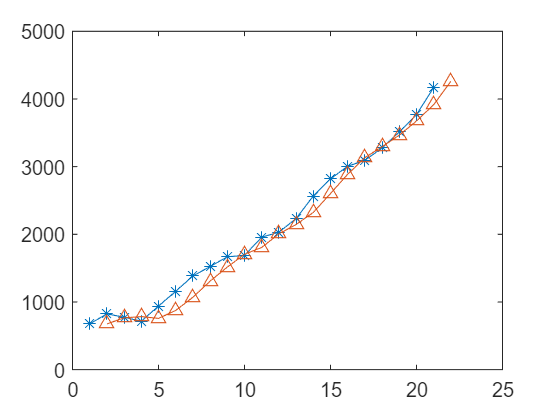

plot(yhat,'^-')

hold off